The `sprandsym` command generates a random sparse matrix with prescribed eigenvalues.

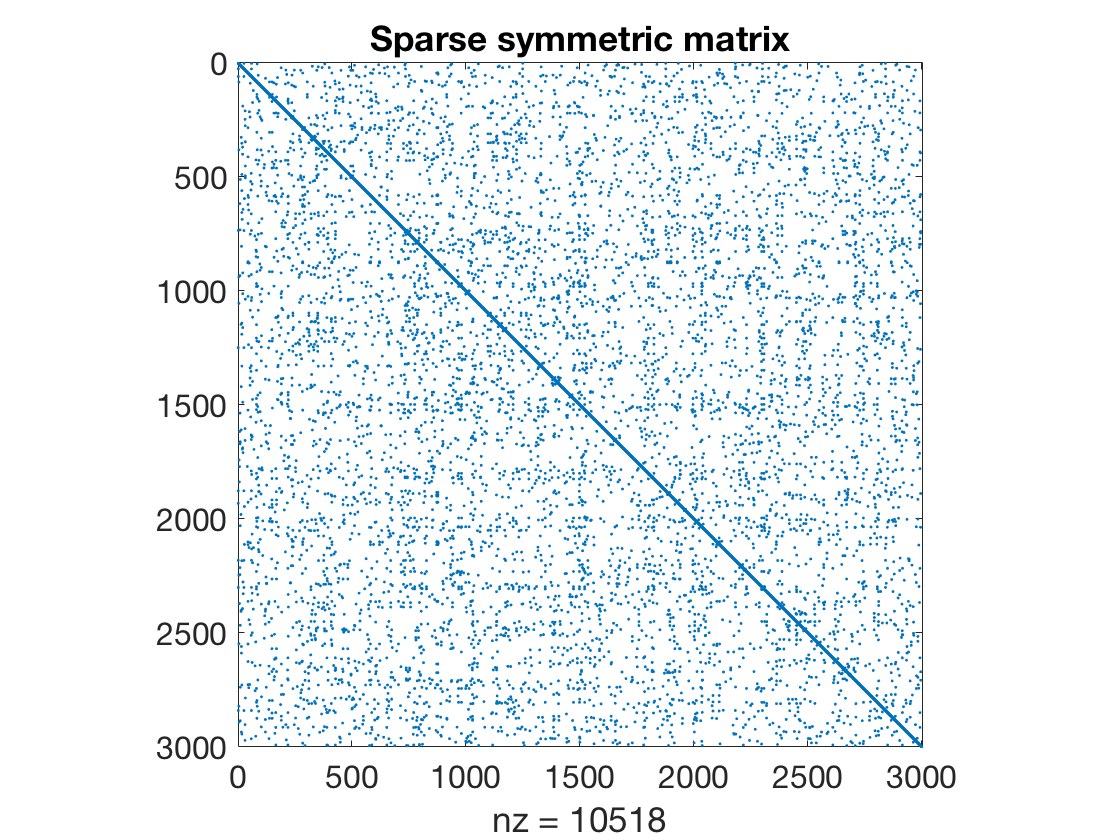

n = 3000;
density = 1.23e-3;
lambda = 1./(1:n);
A = sprandsym(n,density,lambda);
spy(A)
title('Sparse symmetric matrix')    % ignore this line

eigs(A,5)    % largest magnitude

ans =    1.000000000000000
   0.500000000000000
   0.333333333333333
   0.250000000000000
   0.200000000000000


eigs(A,5,0)  % closest to zero

ans =    1.0e-03 *

   0.333333333333336
   0.333444481493829
   0.333555703802535
   0.333667000333667
   0.333778371161546


The scaling of time to solve a sparse linear system is not easy to predict unless you have some more information about the matrix (such as bandedness). But it will typically be a great deal faster than the dense or full matrix case.

x = 1./(1:n)';  b = A*x;
tic, sparse_err = norm(x - A\b), sparse_time = toc

sparse_err =      1.097175099960157e-14


sparse_time =    0.004513021000000


A = full(A);
tic, dense_err = norm(x - A\b), dense_time = toc

dense_err =      3.080590900909823e-14


dense_time =    0.904949492000000
